Digital Signal Processing Lab (EE-384L)

# Assignment No. 8:   **Inverse Systems**

### Reg. No. :   **2016-EE-189**

## Task 1

**Statement:**

Consider a system $H\left(z\right)$ which has the following poles and zeros:

- 4 poles at $z=0$

- 4 zeros at $z=0\ldotp 9e^{j\;0\ldotp 6\pi } ,\;0\ldotp 9e^{-j\;0\ldotp 6\pi } ,\;1\ldotp 25e^{j\;0\ldotp 8\pi } ,\;1\ldotp 25e^{-j\;0\ldotp 8\pi }$

Consider a signal $x\left\lbrack n\right\rbrack$,


$$x\left\lbrack n\right\rbrack \;=\;\textrm{sinc}\left(\frac{\pi }{16}\left(n-50\right)\right)\;\cos \left(\omega_c \;n\right)$$


**Question (1):**

Draw the magnitude, phase and group delay response of the system using MATLAB. Do not use MATLAB’s builtin functions.

**Answer (1):**

The system $H\left(z\right)$ described above will have the following expression,


$$H\left(z\right)\;=\;\frac{\left(z-0\ldotp 9e^{j\;0\ldotp 6\pi } \right)\left(z-0\ldotp 9e^{-j\;0\ldotp 6\pi } \right)\left(z-1\ldotp 25e^{j\;0\ldotp 8\pi } \right)\left(z-1\ldotp 25e^{-j\;0\ldotp 8\pi } \right)}{z^4 }$$



$$H\left(z\right)\;=\;\left(1-0\ldotp 9e^{j\;0\ldotp 6\pi } {\;z}^{-1} \right)\left(1-0\ldotp 9e^{-j\;0\ldotp 6\pi } {\;z}^{-1} \right)\left(1-1\ldotp 25e^{j\;0\ldotp 8\pi } {\;z}^{-1} \right)\left(1-1\ldotp 25e^{-j\;0\ldotp 8\pi } {\;z}^{-1} \right)$$


Note that it is of the form,


$$H\left(z\right)\;=\;\left(1-a_1 \;z^{-1} \right)\left(1-{a_1 }^{\ast } \;z^{-1} \right)\left(1-a_2 \;z^{-1} \right)\left(1-{a_2 }^{\ast } \;z^{-1} \right)$$


where $a_1 =0\ldotp 9e^{j\;0\ldotp 6\pi }$ and $a_2 =1\ldotp 25e^{j\;0\ldotp 8\pi }$. All of its 4 poles are at $z=0$; 2 zeros (conjugate pair) are inside the unit-circle, and the other 2 (also conjugate pair) are outside the unit-circle.

The code, along with results (inline), to compute & plot various responses from $H\left(z\right)$ expression above, starts on the next page.

***Note:  ***The various functions used in the code ($\textrm{markOnPlot}\left(\right)$, $\textrm{plot2SeqDTFT}\left(\right)$, $\textrm{plot3SeqDTFT}\left(\right)$) have been defined at the end of report.

% <task> plot magnitude and phase response of given H(z)

% define z-domain expression (symbolically)
syms z;
a1 = 0.9*exp(1i*0.6*pi);
a2 = 1.25*exp(1i*0.8*pi);
Hz_N = (z-a1)*(z-conj(a1))*(z-a2)*(z-conj(a2));     % numerator of H(z)
Hz_D = z^4;                                         % denominator of H(z)
Hz = Hz_N/Hz_D;

% display H(z) expression
disp('H(z) = '); disp(vpa(Hz, 4))

H(z) = 


$$\frac{\left(z+1.011-0.7347\,\mathrm{i}\right)\,\left(z+1.011+0.7347\,\mathrm{i}\right)\,\left(z+0.2781-0.856\,\mathrm{i}\right)\,\left(z+0.2781+0.856\,\mathrm{i}\right)}{z^{4}}$$

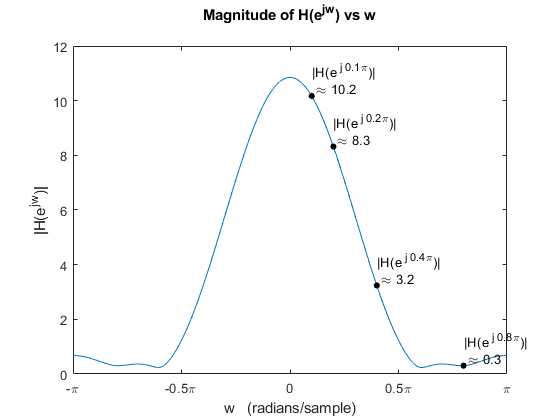


% obtain frequency response H(w) expression from H(z)
% by substituting z = e^(jw)
syms w_;
Hw = subs(Hz, {z}, {exp(1i*w_)});

% compute frequency response H(w) for w = [-pi, pi]
dw = 0.001;
w = -pi:dw:pi;
Hw = subs(Hw, {w_}, {w});
Hw = double(Hw);

% obtain magnitude and phase of H(w)
Hw_mag = abs(Hw);
Hw_arg = phase(Hw);                 % unwrapped phase (in radians)
Hw_ARG = angle(Hw);                 % wrapped phase (in radians)

% frequencies to be noted/marked on the response plots
wvals = [0.1, 0.2, 0.4, 0.8]*pi;

% plot magnitude of H(w) vs w
fig = figure; 
plot(w, Hw_mag);
xlabel('w   (radians/sample)'); 
ylabel('|H(e^{jw})|');
title({'Magnitude of H(e^{jw}) vs w';''});
setDTFTradialAxis(1);
markOnPlot(wvals, w, Hw_mag, dw, [], 0.65, {'|H(e^{ j ', '\pi})|', ''}, pi);

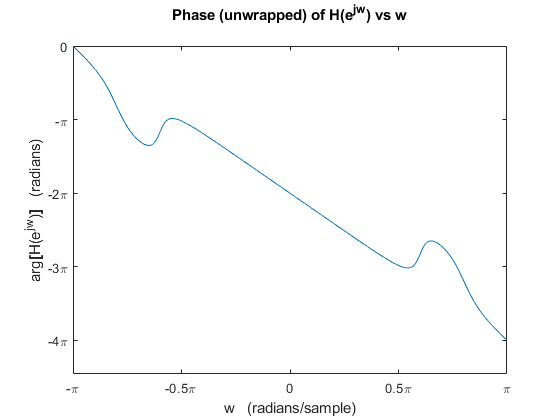


% plot phase (unwrapped) of H(w) vs w
fig = figure; 
plot(w, Hw_arg);
xlabel('w   (radians/sample)'); 
ylabel('arg{\bf[}H(e^{jw}){\bf]}   (radians)');
title({'Phase (unwrapped) of H(e^{jw}) vs w';''});
setDTFTradialAxis(1, 1, 1);

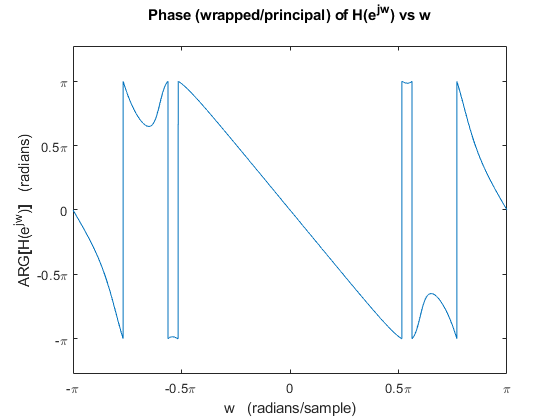


% plot phase (wrapped/principal) of H(w) vs w
fig = figure; 
plot(w, Hw_ARG);
xlabel('w   (radians/sample)'); 
ylabel('ARG{\bf[}H(e^{jw}){\bf]}   (radians)');
title({'Phase (wrapped/principal) of H(e^{jw}) vs w';''});
setDTFTradialAxis(1, 0.5, 1);

Now, the group delay for $H\left(e^{j\omega \;} \right)$ is given by,


$$\tau \left(\omega \right)\;=\;\textrm{grd}\left\lbrack H\left(e^{j\omega } \right)\right\rbrack \;=\;-\frac{d}{d\omega \;}\left\lbrace \arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack \right\rbrace$$


where the derivative of (unwrapped) phase may be computed using,


$$\frac{d}{d\omega \;}\left\lbrace \arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack \right\rbrace \;=\;\lim_{\Delta \omega \;\to \;0} \frac{\arg \left\lbrack H\left(e^{j\;\left(\omega \;+\;\Delta \omega \right)} \right)\right\rbrack -\arg \left\lbrack H\left(e^{j\omega } \right)\right\rbrack }{\Delta \omega }$$


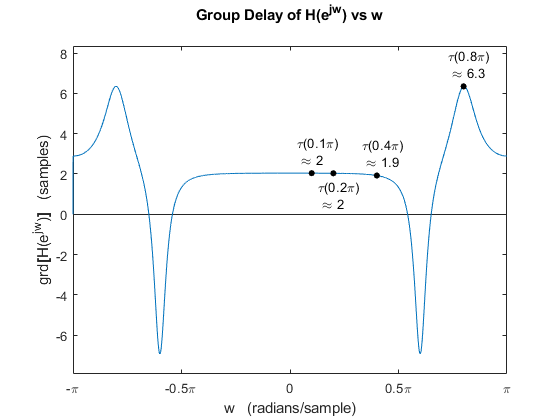


% <task> plot group-delay of given H(z)

dw = (w(end)-w(1))/(length(w)-1);           % compute the w-step-size 'dw' used in w-array

% obtain group-delay of H(w)
Hw_grd = -([Hw_arg 0]-[0 Hw_arg])/dw;
Hw_grd = Hw_grd(1:(length(Hw_grd)-1));

% plot group-delay of H(w) vs w
fig = figure; 
plot(w, Hw_grd);
xlabel('w   (radians/sample)'); ylabel('grd{\bf[}H(e^{jw}){\bf]}   (samples)');
title({'Group Delay of H(e^{jw}) vs w';''});
setDTFTradialAxis(1); ylim([min(Hw_grd)-1 max(Hw_grd)+2]);
markOnPlot(wvals, w, Hw_grd, dw, -0.07*pi, [1 -1 1 1]*1.1, {'\tau(', '\pi)', ''}, pi);

**Question (2):**

Is the system stable? Is the system causal?

**Answer (2):**

Consider the pole-zero plot of this system $H\left(z\right)$, as drawn below.

% extract CCDE coefficients (b's and a's) from H(z) expression
[N, D] = numden(Hz);
b = coeffs(N, 'All');   a = coeffs(D, 'All');
b = double(b./a(1));    a = double(a./a(1));
disp('b ='); disp(b);   disp('a ='); disp(a);

b =
    1.0000    2.5788    3.4975    2.5074    1.2656

a =
     1     0     0     0     0



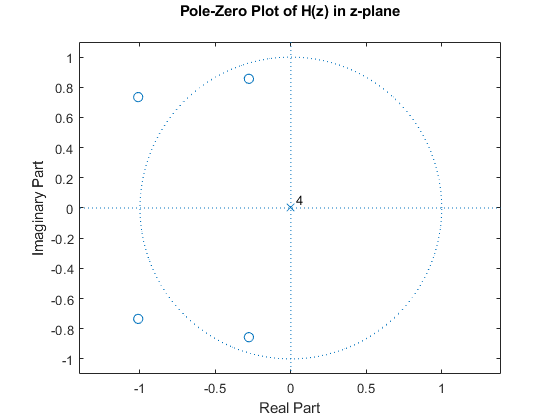


% plot the pole-zero map of H(z) using extracted b's and a's
figure;
zplane(b, a);
title({'Pole-Zero Plot of H(z) in z-plane';''});

As can be seen above, all poles of $H\left(z\right)$ lie within the unit-cricle. Furthermore, all 4 poles lie at origin. This means the only possible ROC is the one extending outward from $|z|>0$. So, ROC is all of z-plane except $z=0$.

Since the unit-circle lies in ROC, the system is stable. As here, ROC extends outward from outermost pole ($z=0$), so $h\left\lbrack n\right\rbrack$ is a right-sided function (possibly with $h\left\lbrack n\right\rbrack =0\;\;\forall \;\;n<0$). Hence the system is also causal.

So the system represented by $H\left(z\right)$ is causal and stable.

**Question (3):**

Pass $x\left\lbrack n\right\rbrack$ through $H\left(z\right)$ for $\omega_c =0\ldotp 1\pi ,\;0\ldotp 2\pi ,\;0\ldotp 4\pi ,\;0\ldotp 8\pi$ and obtain the output signal $y\left\lbrack n\right\rbrack$. 

How does the magnitude of the output signal change with change in $\omega_c$? Can you explain the difference in magnitude corresponding to different $\omega_c$ using the magnitude response of $H\left(z\right)$.

**Answer (3):**

Since MATLAB defines $\textrm{sinc}\left(\right)$ function as $\textrm{sinc}\left(x\right)=\frac{\sin \left(\pi x\right)}{\pi x}$, we'll define $x\left\lbrack n\right\rbrack$ as, $x\left\lbrack n\right\rbrack \;=\;\textrm{sinc}\left(\frac{n-50}{16}\right)\;\cos \left(\omega_c \;n\right)$, i.e. without the extra $\pi$ in MATLAB.

Note that in frequency-domain, this $\textrm{sinc}\left(\right)$ function corresponds to a gate-pulse of certain width ($W$), which is shift-copied to $\omega =\pm \;\omega_c \;\textrm{rad}/\textrm{sample}$ due to the $\cos \left(\right)$ term. Changing $\omega_c$ in $x\left\lbrack n\right\rbrack$ thus changes where the gate-pulse (+ve & -ve) is centered in $x\left\lbrack n\right\rbrack$'s spectrum.

The code, along with the results, to pass $x\left\lbrack n\right\rbrack$ for each $\omega_c$ through $H\left(z\right)$, starts below.

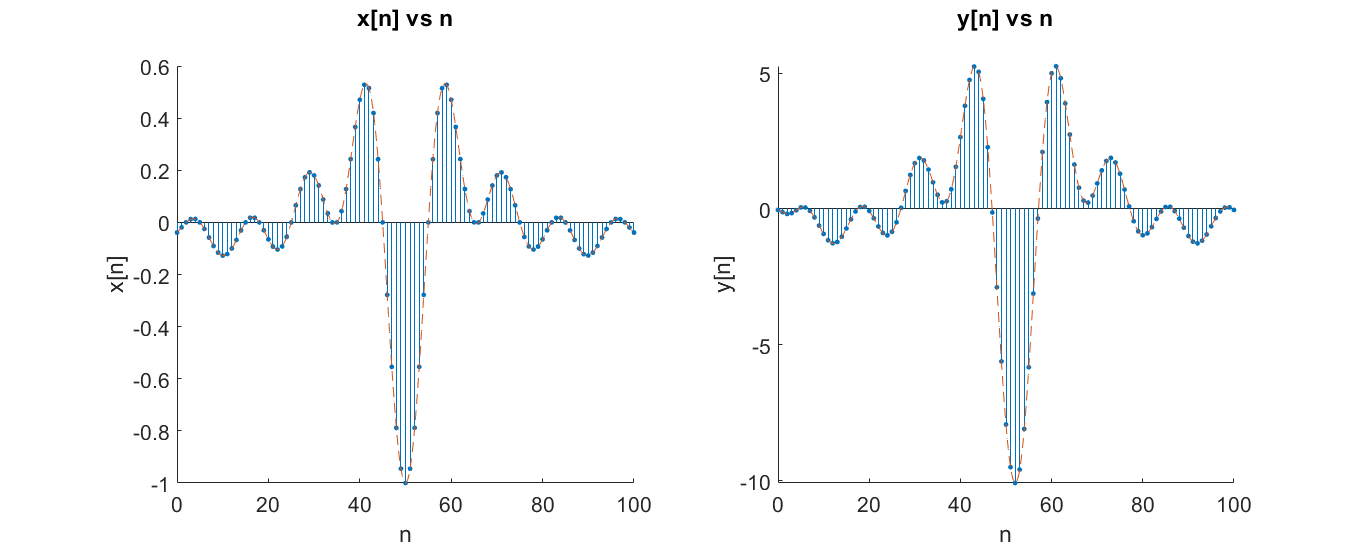

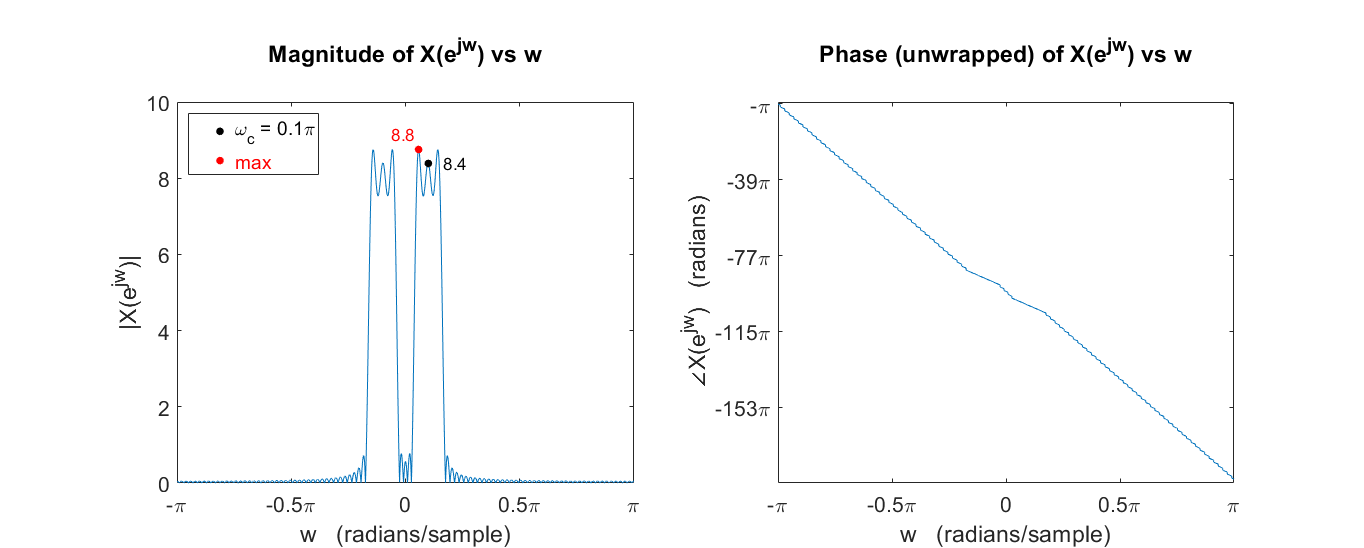

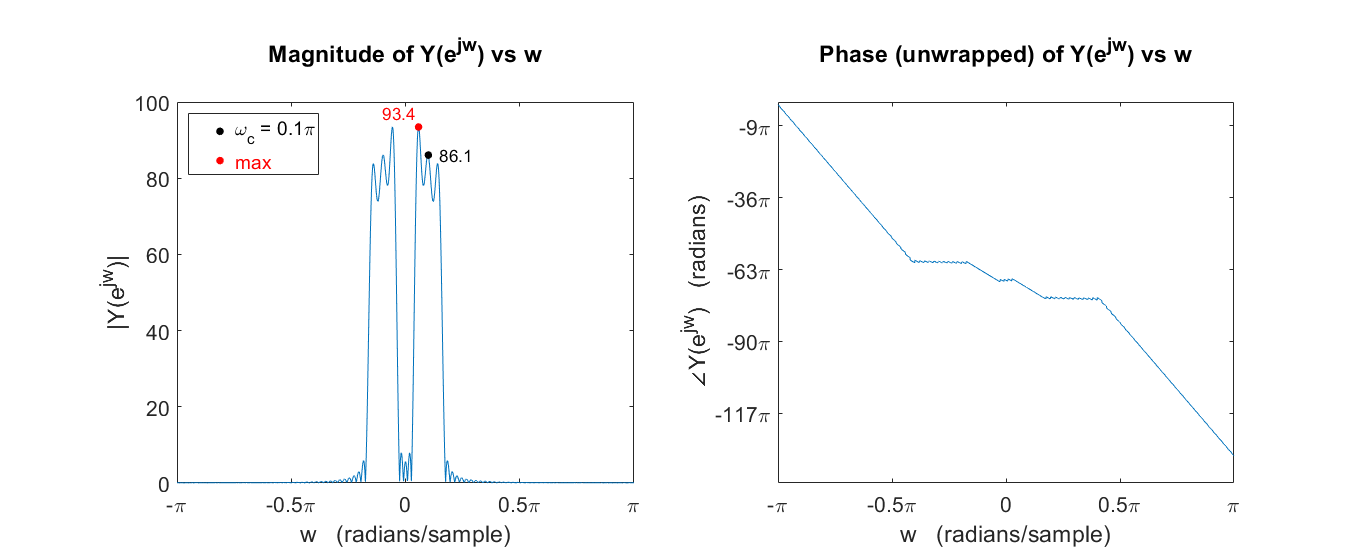

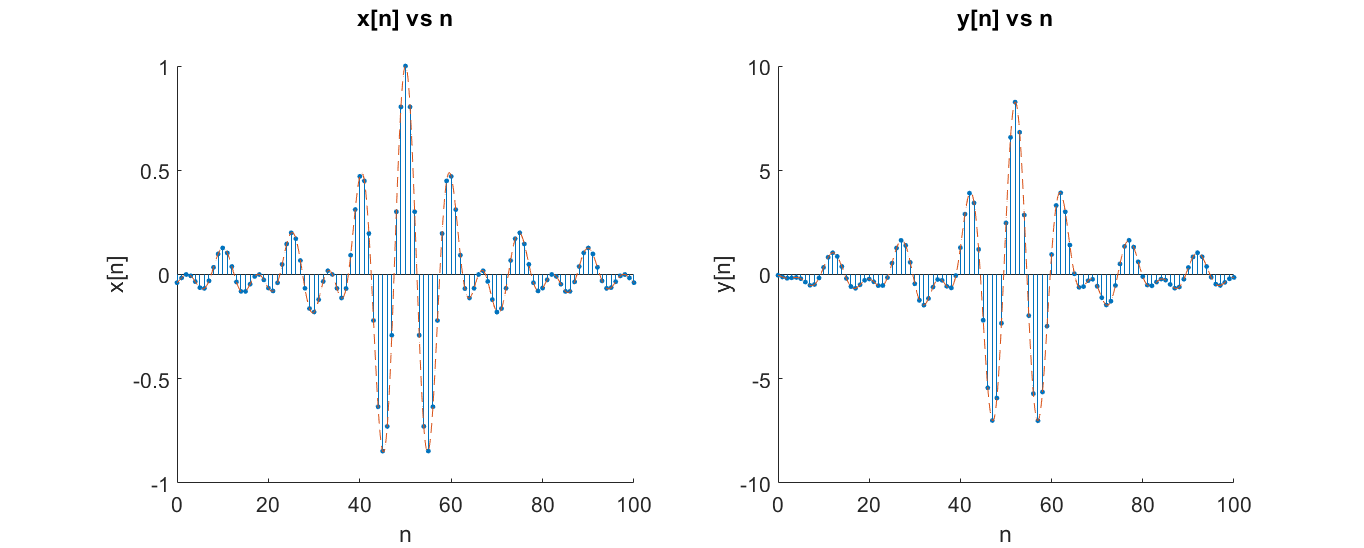

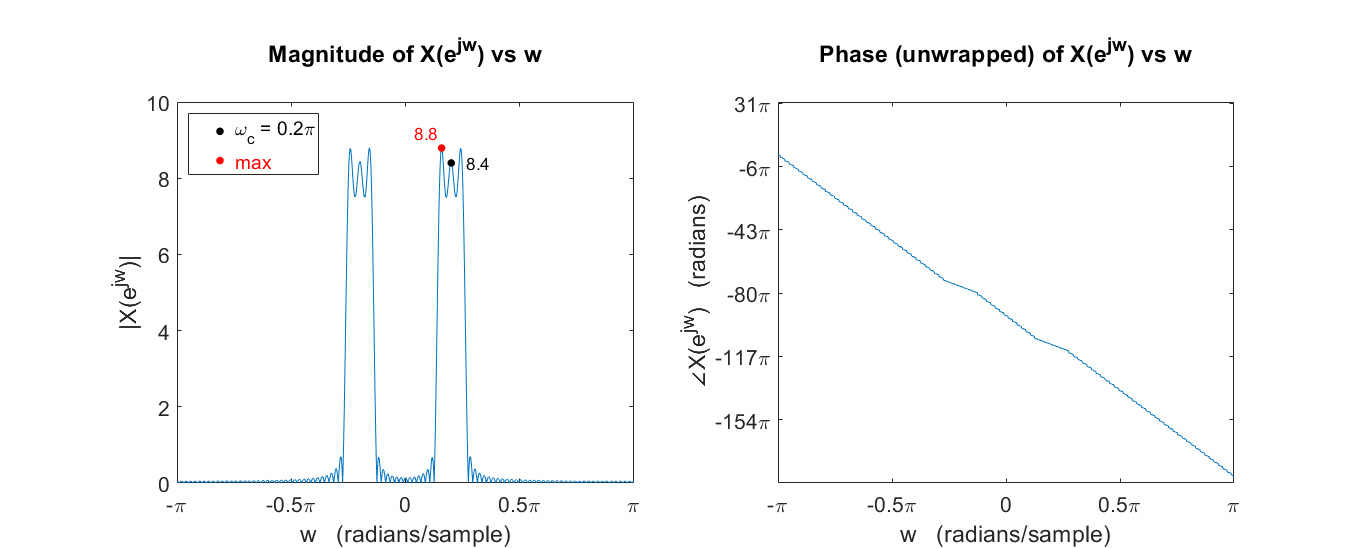

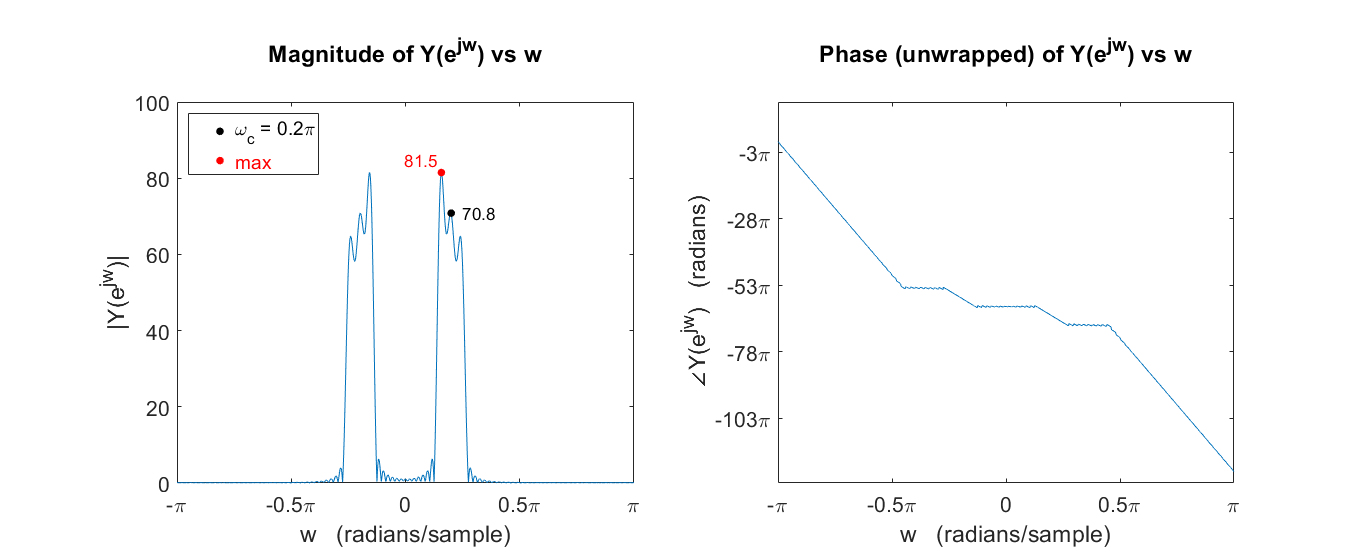

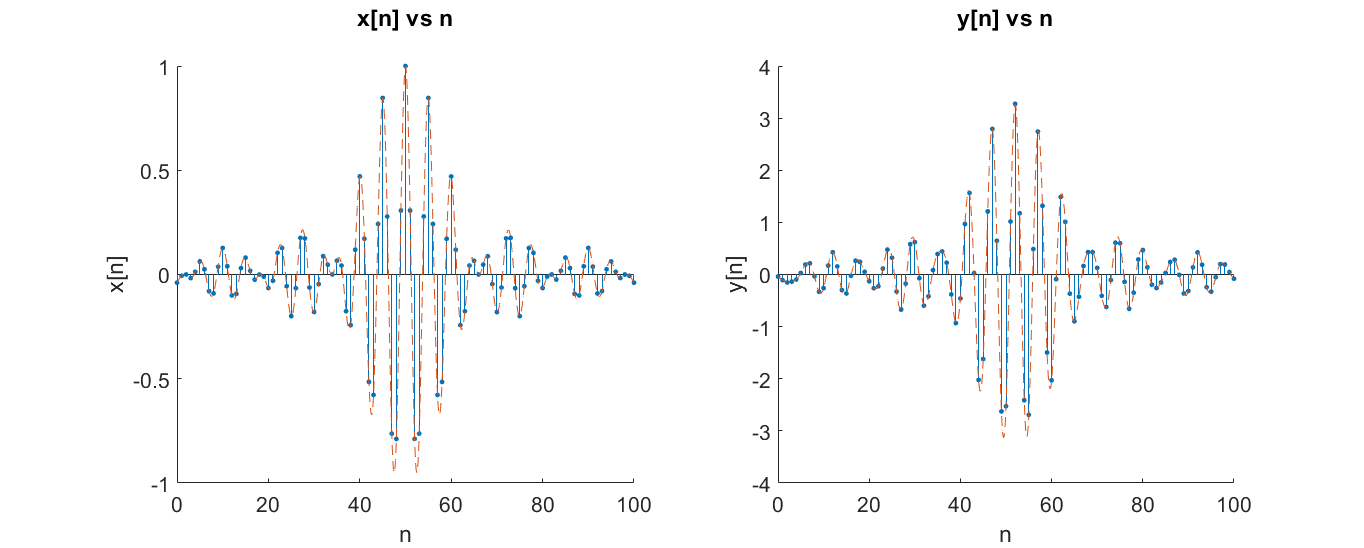

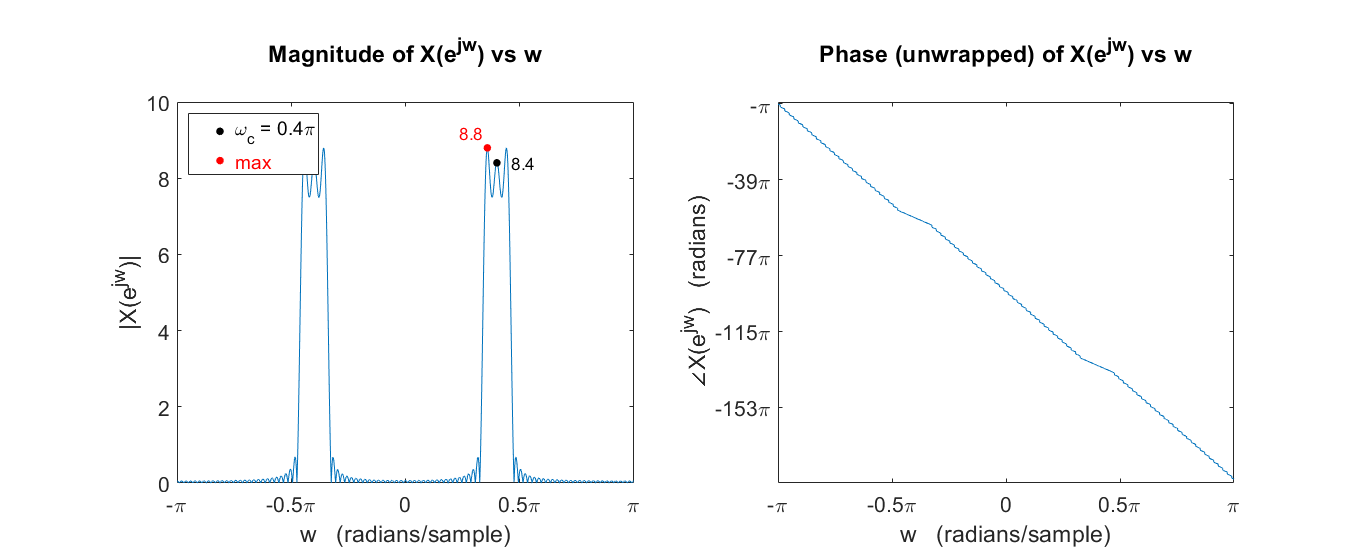

% <task> pass x[n] (for each wc value) through system H(z),
% and plot the output y[n] and its spectrum

wcvals = [0.1, 0.2, 0.4, 0.8]*pi;           % wc values (x[n] center frequencies)
n = 0:100;
x = cell(1, length(wcvals));                % to store x[n] arrays for different wc
y = cell(1, length(wcvals));                % to store y[n] arrays for different wc
ny = cell(1, length(wcvals));               % to store ny arrays for different wc

for i = 1:length(wcvals)
    
    % define x[n] = (sin(pi*(n-50)/16)./(pi*(n-50)/16)).*cos(wc*n)
    wc = wcvals(i);
    x{i} = sinc((n-50)/16).*cos(wc*n);
  
    % compute DTFT X(w)
    w = -pi:0.001:pi;                       % for 1 period [-pi, pi] of DTFT
    Xw = x{i} * exp(-1i * n' * w);          % using matrix-multiplication method
    
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT X(w)
    Xw_mag = abs(Xw);
    Xw_arg = phase(Xw);
    
    % assuming zero initial conditions (rest)
    N_aux = zeros(1, length(a)-1);
    M_init = zeros(1, length(b)-1);
    
    % compute output y[n], with input x[n] to system represented by H(z),
    % using get_system_out() and extracted b's and a's
    [y{i}, ny{i}] = get_system_out(b, a, x{i}, N_aux, M_init);
    
    % compute DTFT Y(w)
    w = -pi:0.001:pi;                       % for 1 period [-pi, pi] of DTFT
    Yw = y{i} * exp(-1i * ny{i}' * w);      % using matrix-multiplication method
    
    % obtain the magnitude and phase (unwrapped, in radians) of DTFT Y(w)
    Yw_mag = abs(Yw);
    Yw_arg = phase(Yw);
    
    % plot sequences x[n] & y[n], and their DTFTs X(w) & Y(w) (magnitude and phase)
    plot2SeqDTFT(n, x{i}, wc, w, Xw_mag, Xw_arg, 'x', 'X', ...
        [0.2 0 -0.04 0.4, 0.15 0 -0.04 0.04*max(Yw_mag)], ...
        ny{i}, y{i}, Yw_mag, Yw_arg, 'y', 'Y', 'left', 'right');

end

In the magnitude plot of $H\left(e^{j\omega } \right)=H\left(\omega \right)$ (Page 3), the magnitude values i.e. gains for each of the $\omega_c$ frequencies have been marked. These gain values are as follows:


$$\begin{array}{l}
|H\left(\;\;\;0\ldotp 1\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;10\ldotp 2\\
|H\left(\;\;\;0\ldotp 2\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;8\ldotp 3\\
|H\left(\;\;\;0\ldotp 4\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;3\ldotp 2\\
|H\left(\;\;\;0\ldotp 8\pi \;\;\textrm{rad}/\textrm{sample}\;\;\;\right)|\;\;\;\;\;\approx \;\;\;\;\;0\ldotp 3
\end{array}$$


Since $H\left(z\right)$ is not an all-pass system, the various frequency components (centered around $\omega_c$) in $x\left\lbrack n\right\rbrack$ are distorted (in magnitude) by different amounts. Following table summarizes the variation in magnitude from $X\left(e^{j\omega } \right)$ to $Y\left(e^{j\omega } \right)$ after being passed through $H\left(z\right)$:


$$\matrix{\cr
\text{ }    	&|X(e^{j\omega})|	&|Y(e^{j\omega})| & \frac{|Y(e^{j\omega})|}{|X(e^{j\omega})|}=|H(e^{j\omega})|\cr
& \text{---------------------------------} & \text{---------------------------------}& \text{---------------------------------}  \cr
\text{center frequency of x[n] \,\,\,} (\omega_c) & \matrix{\text{at }\omega_c &&&& \text{max}} &  \matrix{\text{at }\omega_c &&&& \text{max}}  &  \matrix{\text{at }\omega_c &&&& \text{max}}\cr
\text{--------------------------------------------}  & \text{----------------------------------} & \text{---------------------------------} & \text{---------------------------------}  \cr
0.1\pi \text{\, \, \, \,\,rad/sample}   & \matrix{8.4 &&&&& 8.8}   &  \matrix{\text{86.1 \;\;\;\;\;\;\;\;\;\;\;\; 93.4}}		& \matrix{\text{10.3 \;\;\;\;\;\;\;\;\;\;\;\; 10.6}}	\cr
0.2\pi \text{\, \, \, \,\,rad/sample}   & \matrix{8.4 &&&&& 8.8}   &   \matrix{\text{70.8 \;\;\;\;\;\;\;\;\;\;\;\; 81.5}}		& \matrix{\text{\;\;8.4  \;\;\;\;\;\;\;\;\;\;\;\; 9.26}} \cr
0.4\pi \text{\, \, \, \,\,rad/sample}   & \matrix{8.4 &&&&& 8.8}   &  \matrix{\text{\;\;\;28 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\; 38}}	&  \matrix{\text{\;\;3.3 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 4.3}} \cr
0.8\pi \text{\, \, \, \,\,rad/sample}   & \matrix{8.4 &&&&& 8.8}   &  \matrix{\text{\;\;2.6 \;\;\;\;\;\;\;\;\;\;\;\;\;\; 3.3}}       &  \matrix{\text{\;\;0.3 \;\;\;\;\;\;\;\;\;\;\;\; 0.38}}\cr
}
$$


The ratio of output to input magnitude (shown in the last 2 columns of above table) corresponds to the gain provided by the system $H\left(z\right)$ to the input. Note that the gain values at center frequencies $\omega_c$, calculated in above table, match (approximately) with the magnitude values noted further above from the $|H\left(e^{j\omega \;} \right)|$ plot at respective frequencies. Thus the output magnitude is given by,


$$|Y\left(e^{j\omega } \right)|\;=\;|X\left(e^{j\omega } \right)|\;|H\left(e^{j\omega } \right)|$$


And since $H\left(e^{j\omega } \right)$ has different (widely-varying) magnitudes at different frequencies $\omega$, this explains the changing magnitude of output $Y\left(e^{j\omega \;} \right)$ based on the frequency-content in input $X\left(e^{j\omega } \right)$ (centered around $\pm \;\omega_c$).

*Next Question/Answer starts from the next page.*